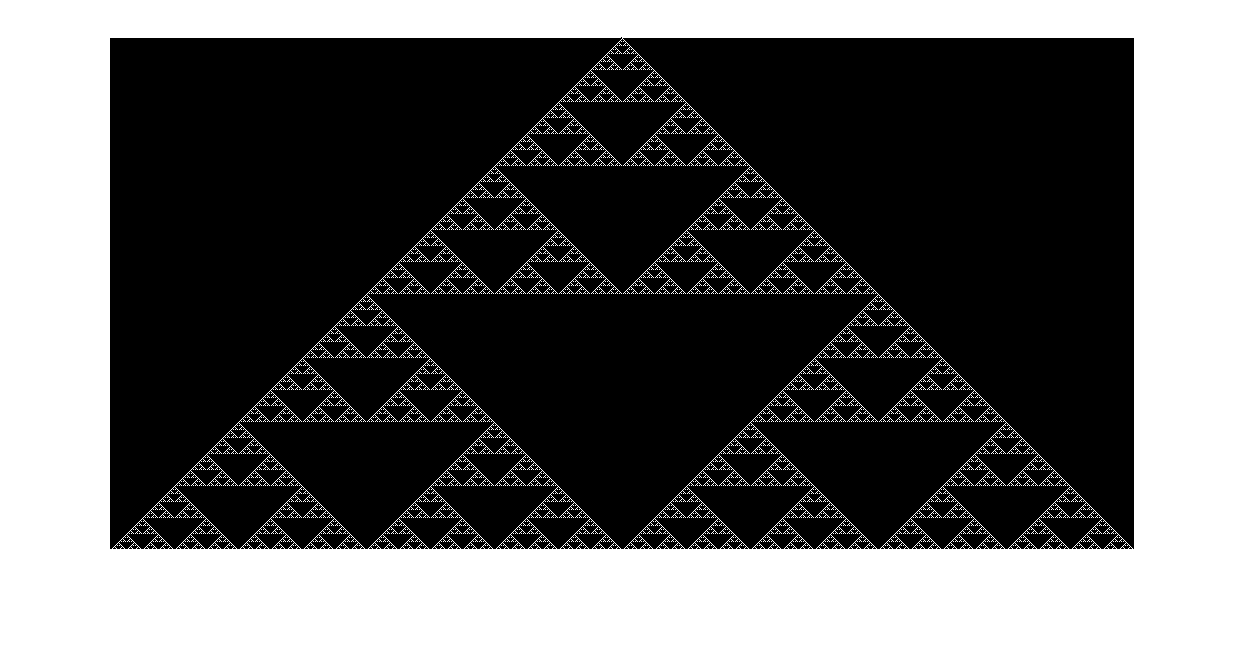

a = 1024;
Img = ones(round(a/2), a);
Img(1,round(a/2)) = 0;
for i = 2:round(a/2)
    for j = 2:(a-1)
        rule = 4*Img(i-1,j-1) + 2*Img(i-1,j) + Img(i-1, j+1);
        if (rule == 4) || (rule == 3) || (rule == 1)
            Img(i,j) = 1;
        else
            Img(i,j) = 0;
        end
    end
    
    rule = 4*Img(i-1,a) + 2*Img(i-1,1) + Img(i-1, 2);
    if (rule == 4) || (rule == 3) || (rule == 1)
            Img(i,1) = 1;
        else
            Img(i,1) = 0;
    end
    
    rule = 4*Img(i-1,a-1) + 2*Img(i-1,a) + Img(i-1, 1);
    if (rule == 4) || (rule == 3) || (rule == 1)
            Img(i,a) = 1;
        else
            Img(i,a) = 0;
    end
    %disp(Img(i-1,:))
end
imshow(Img)